modulePath = 'C:\Users\Asus\Studia\Indywidualny Program Studiów\IPS - Projekt\dane - semestr 5\MATLAB_project\python_modules';
insert(py.sys.path, int32(0), modulePath);
load('C:\Users\Asus\Studia\Indywidualny Program Studiów\IPS - Projekt\dane - semestr 5\MATLAB_project\ab_diff_zestaw.mat')

function results_py = model_hybrid(y_train, y_test, step_length, season_period)
    py_model = py.importlib.import_module("HoltWintersModule_multiCPU");
    results_py = py_model.forecast_holt_winters_parallel(...
        y_train,...
        y_test,...
        step_length,...
        season_period ...
        ).double;
end

% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);

dlugosc_testu_oryginalna = 2880; % Horyzont w oryginalnej dziedzinie czasu (2880 próbek)

test_length = dlugosc_testu_oryginalna;
time_step = 96;

train_data = ab_diff_train_norm;
test_data = ab_diff_test_norm;

% Przewidywania A1 - model hybrydowy
prediction = model_hybrid(train_data, test_data(1:test_length), time_step, 96);

Rozpoczynanie prognozy (Parallel Refitting Expanding Window)...
Rozmiar testowy: 2880, Krok: 96, Pętle: 30
Używam 16 rdzeni CPU
C:\Python314\Lib\site-packages\joblib\externals\loky\backend\resource_tracker.py:146: UserWarning: resource_tracker: process died unexpectedly, relaunching. Some folders/semaphores might leak.
  warnings.warn(
Prognoza zakończona.


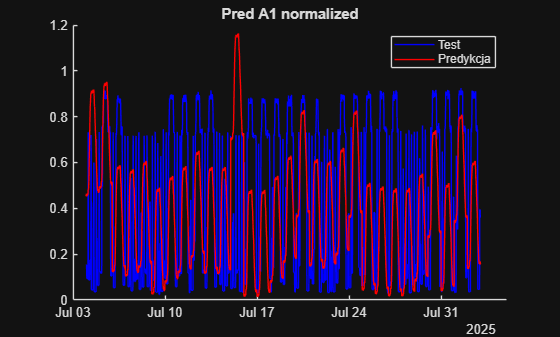

% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:test_length), test_data(1:test_length), 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:length(prediction)), prediction, 'Color','red','DisplayName','Predykcja');
title('Pred A1 normalized');
legend;

y_test = ab_diff_test_norm(1:length(prediction))';

mae_score = mae(y_test, prediction)

mae_score = 0.2601

mape_score = mape(y_test, prediction)

mape_score = 115.2002

rmse_score = rmse(y_test, prediction)

rmse_score = 0.3284

r2_classic = R2_classic(y_test, prediction)

r2_classic = 0.1003

r2_alt = R2_alt(y_test, prediction)

r2_alt = 0.5132

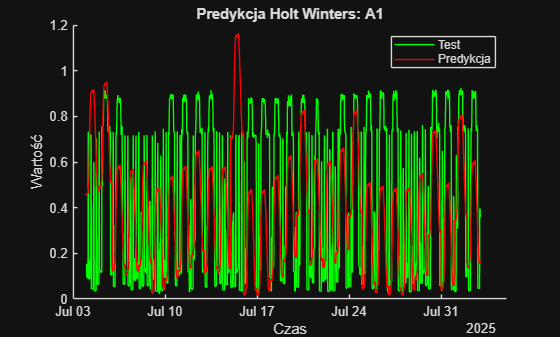


figure;
hold on;
%plot(ab_diff_train.Time, ab_diff_train_norm, 'Color','blue','DisplayName','Trening');
plot(ab_diff_test.Time(1:length(prediction)), ab_diff_test_norm(1:length(prediction)), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:length(prediction)), prediction, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja Holt Winters: A1")
legend;

% Tworzenie tabeli z czasem, danymi i predykcją
T_z_czasem = table(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ...
                   ab_diff_test_norm(1:dlugosc_testu_oryginalna), ...
                   prediction(1:dlugosc_testu_oryginalna)', ...
    'VariableNames', {'Czas', 'Dane_Prawdziwe', 'Predykcja'});

writetable(T_z_czasem, "pred_ab_HW_" + num2str(time_step) + "month.xlsx");